## Qr Algorithm

the QR algorithm is a very impoprtant algorthm that allows us to find a Schur decomposition of a given matrix A, and consequently we can find the eigenvalue.

We will give a series of implementation of this problem.

### Simple QR Algorithm:

In this implementation we will see the easisest way to implement this algorithm, that is in a series of product using the result of the **QR decomposition algorithm**

format short
%Normal QR algorithm
A = Generate_Large_Matrix(4);
tic
A = Normal_QR(A,100);
toc

Elapsed time is 0.011618 seconds.


A

A =     4.0000   -2.2675   -3.8241    5.9958
    0.0000    3.0000    0.3519   -2.7374
    0.0000   -0.0000    2.0000    0.2484
   -0.0000   -0.0000   -0.0000    1.0000


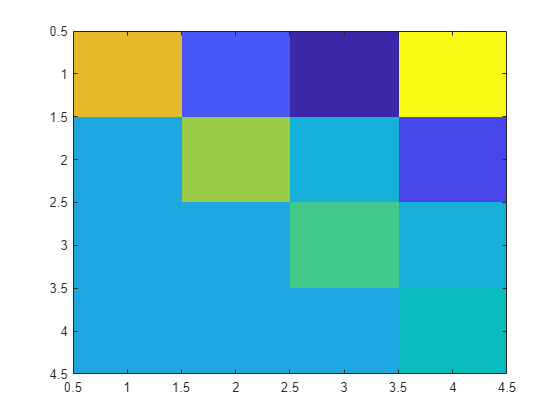

imagesc(A)

This implementation is slow in convergence and it requires a loat of iteration for the computation of the **QR decomposition, **we can try to speed this up

### Hessenberg Reduction

Using as imput a matrix in the Hessenber form we can reduce the time it takes to compute the QR algorithm.

%Hessemberg QR
A = Generate_Large_Matrix(5);
H = Hessenberg_reduction(A);
tic
H = Normal_QR(H, 500);
toc

Elapsed time is 0.006318 seconds.


H

H =     5.0000   -0.0053    6.7512   -6.8864   -0.7094
    0.0000    4.0000   -2.4825    0.7639   -1.1969
   -0.0000    0.0000    3.0000    0.1233   -0.7095
   -0.0000    0.0000    0.0000    2.0000   -0.2571
         0    0.0000   -0.0000    0.0000    1.0000


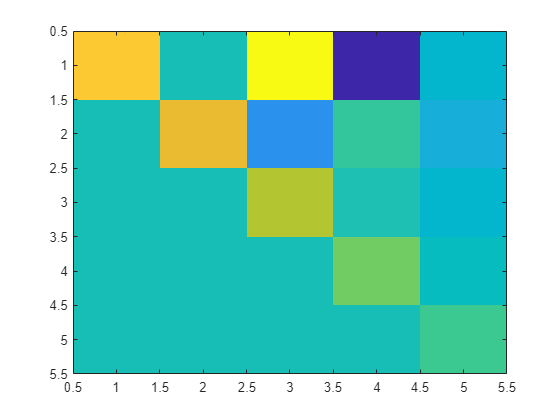

imagesc(H)

In the previou section we still used the basic QR Algorithm, now we will try to incorporate the givens rotation to annichilate the element under the main diagonal during the QR step.

A = Generate_Large_Matrix(6);
A = Hessenberg_reduction(A);
tic
A = Unshifted_QR(A,50);
toc

Elapsed time is 0.003842 seconds.


A

A =     6.0000    0.5297    0.6544   -1.5979    0.0119   -0.1651
    0.0001    5.0000    0.3438    0.1618    1.3927  -14.5986
    0.0000    0.0000    4.0000   -0.3483    1.5172   -1.8276
    0.0000         0    0.0000    3.0000    0.3853   -0.6736
    0.0000         0         0    0.0000    2.0000    0.3113
    0.0000         0         0         0   -0.0000    1.0000


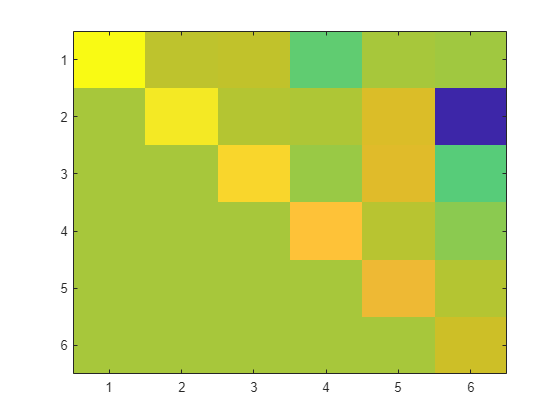

imagesc(A)

### Shift and deflation

we can still speed up this by incorporating some spectral shift with a deflation step

%Shifted QR factorization
%Real numbers
A = Generate_Large_Matrix(9);
H = Hessenberg_reduction(A);
tic
H = Shifted_QR(H);
toc

Elapsed time is 0.003278 seconds.


H

H =     9.0000   -1.6172    0.2778    2.9028    0.7914    2.1179    0.1007    0.7450   -8.2445
         0    1.0000   -0.1979    2.2562   -1.0618    0.1398    0.6789    0.7822    2.9379
         0         0    8.0000   -0.6455    1.6011   -6.4892    1.9477    2.2325    0.5245
         0         0         0    7.0000   -1.2550   -4.7568    1.4172    2.7998   16.2381
         0         0         0         0    2.0000    0.1177   -2.3030    1.0053    1.8910
         0         0         0         0         0    3.0000    1.0237    0.3896    5.6140
         0         0         0         0         0         0    6.0000    0.5867    1.6530
         0         0         0         0         0         0         0    4.0000   -0.9044
         0         0         0         0         0         0         0         0    5.0000


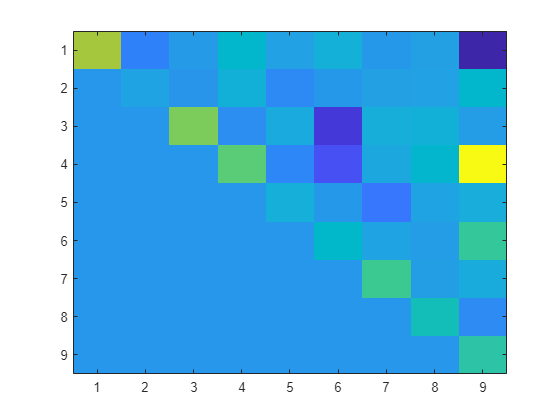

imagesc(H)

And with complex numbers

%Shifted QR factorization
%Complex numbers
N = 8;
cMatrix = complex(rand(N, N), rand(N,N));
idx = randperm(N,3);
cMatrix(idx(1),:) = cMatrix(idx(2),:) + rand * cMatrix(idx(3),:);
rank(cMatrix)

ans = 7

H = Hessenberg_reduction(cMatrix);
tic
H = Shifted_QR(H);
toc

Elapsed time is 0.003392 seconds.


H

H =    1.3040 + 1.5883i   0.5276 - 0.2425i  -0.3038 - 0.3153i  -0.5326 + 0.0763i  -0.3000 + 0.0783i   0.0641 + 0.1699i   0.0797 - 0.2851i  -0.1525 - 0.2754i
   0.0000 + 0.0000i  -0.1217 + 1.1087i   0.1804 - 0.8400i  -0.8760 - 0.6331i   0.3004 + 0.0100i   0.2910 + 0.1526i   0.2377 + 0.6653i  -0.2453 + 0.0294i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.1631 + 0.7733i   0.7581 + 0.3760i   0.3006 - 0.3049i  -0.2177 - 0.3727i   0.1294 + 0.0147i   0.0360 + 0.3166i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.4930 - 0.0108i   0.0306 - 0.0865i  -0.1989 - 0.3057i   0.1878 - 0.1634i  -0.1918 + 0.2589i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.1591 - 0.0439i   0.0503 + 0.0055i   0.0171 - 0.1660i   0.0178 - 0.0019i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0767 + 0.0447i  -0.0646 + 0.0834i  -0.0073 - 0.0664i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  

Householder hessenberg

A = Generate_Large_Matrix(9);
H = Householder_hessenberg(A);
tic
H = CHASE_THE_BULGE(H);
toc

Elapsed time is 0.005234 seconds.


H

H =     9.0000    0.3403   -0.0773    0.1948    0.6786    1.4587   -0.1211   -0.2058    0.1643
         0    0.9979    1.8902   -1.9025   -1.7151   -0.9027    0.4600    1.8216  -12.3395
         0   -0.0079    8.0021    0.4397    0.5399    0.1101    0.7617    2.9054  -17.4733
   -0.0000   -0.0000         0    6.9932    4.2446    3.6627   -1.1958    9.3769  -50.5408
   -0.0000    0.0000   -0.0000    0.0080    2.0068   -0.5394    1.9951   -5.3821   24.2357
    0.0000    0.0000   -0.0000   -0.0000         0    2.8997   -0.6054   -0.9457    4.7172
    0.0000    0.0000   -0.0000    0.0000         0    0.5138    6.1003   -0.4312   -2.0121
    0.0000    0.0000         0    0.0000    0.0000   -0.0000         0    4.9996   -3.8330
   -0.0000    0.0000    0.0000    0.0000   -0.0000         0         0   -0.0001    4.0004


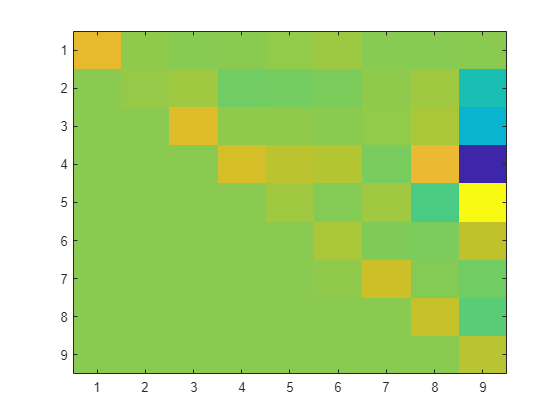

imagesc(H)

## Test Con matrici "Grandi"

A = Generate_Large_Matrix(50);
tic
A = Normal_QR(A,500);
toc

Elapsed time is 0.207596 seconds.


A

A =    50.0000    0.1314   -0.0521   -0.0351    0.9417   -0.0335    0.5121    1.7787    0.1915    1.2192    0.1158   -2.7930    0.8224   -0.6730    0.6780    4.3566    4.2315    3.2550   -0.4305   -9.1401   -2.7807    2.2255    1.0690    2.4726    3.1588   -1.4948   10.3252   -2.4293   -3.6053  -17.5704   -0.7388  -13.6148    4.4517   -7.9865    6.8480   -6.6391  -25.8164   -5.0413  -19.0943  -19.0230  -21.3195  -19.1756   17.4506    2.3372   -4.4554  -10.4880  -33.1231   29.7729   25.8472   66.5986
   -0.0000   49.0000    0.0422    1.0057    0.1374    0.3028   -0.7821    0.5803   -2.1723    1.1926   -2.3439   -1.6712   -2.6456   -2.2668   -0.1361   -2.3835   -3.7699    0.9318   -0.3834    7.3514    1.2294   -2.5414    1.6433   -2.3128    2.7627   -1.7831    7.0136   -0.9664    0.2458   -4.1705    5.9355    0.0505    6.9665    4.3010    6.7187  -14.8612   -2.8067  -11.2251  -19.7176    5.8625    2.7377  -11.9124   28.1234  -30.6304   18.9753  -27.7546   -8.0829   24.2157    6.3491  -20

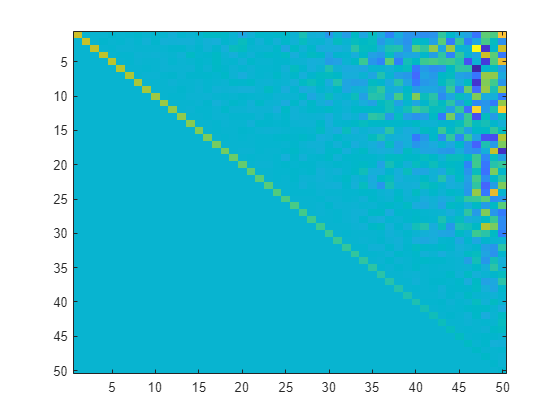

imagesc(A)

A = Generate_Large_Matrix(50);
H = Hessenberg_reduction(A);
tic
H = Unshifted_QR(H,1000);
toc

Elapsed time is 0.313110 seconds.


disp(H);

  Columns 1 through 22

   50.0000    0.0579   -0.2262    0.4215   -0.0826   -0.3175    0.0515   -0.1879   -2.3263    0.1424    2.5569   -0.7109   -0.9749   -0.2107    2.1347    5.7613   -3.5656    1.4463   -0.6840    0.9870   -6.3951   -2.8382
    0.0000   49.0000    0.0757   -0.2475    0.7550    0.6104   -0.6265   -0.7868    1.1811    2.3613    0.3434   -1.3764   -1.0887   -1.5795   -3.4622    0.3291    2.8365   -0.9241   -1.8765   -1.1858  -11.2843    3.5840
    0.0000    0.0000   48.0000   -0.0606   -0.7053    0.7028   -0.2527    0.5652   -1.3394   -0.2554    0.4058   -0.6180   -1.7289   -0.7661   -2.9288   -1.9324    2.4429   -0.3474    1.1218   -1.4522    2.4912   -2.5505
   -0.0000    0.0000    0.0000   47.0000    0.0059   -0.3619    0.0729   -0.2172   -1.0652    2.8123    0.0927   -0.8425   -0.4233   -1.5185    5.0316   -1.9774   -1.0735   -1.9552   -2.4931   -0.9283   -5.6681    2.9532
    0.0000   -0.0000    0.0000    0.0000   46.0000   -0.1969   -0.3934    0.3953    0.6398  

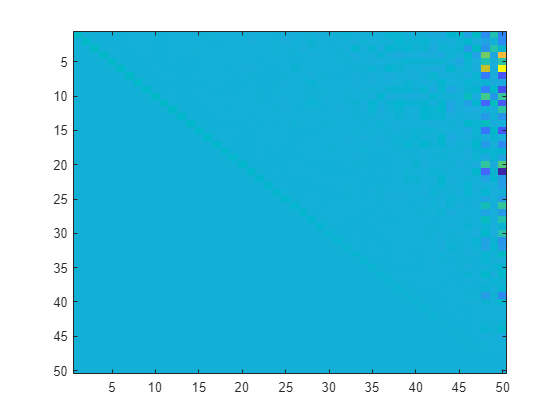

imagesc(H)

A = Generate_Large_Matrix(50);
H = Hessenberg_reduction(A);
tic
H = Shifted_QR(H);
toc

Elapsed time is 0.094081 seconds.


H

H = 1.0e+03 *

    0.0010    0.0103   -0.0004    0.0010   -0.0148    0.0042    0.0020    0.0017   -0.0033   -0.0051   -0.0032    0.0002    0.0039   -0.0038   -0.0078   -0.0027   -0.0133    0.0023    0.0157    0.0058   -0.0076   -0.0090   -0.0091   -0.0012    0.0020    0.0089    0.0037   -0.0164   -0.0092   -0.0019   -0.0004    0.0049    0.0199   -0.0417   -0.0227    0.0015    0.0103    0.0010    0.0191   -0.0532   -0.0156   -0.0138   -0.0118    0.0057    0.1178   -0.1096    0.1657   -0.2386   -0.2236    1.0900
         0    0.0500   -0.0015    0.0003   -0.0006    0.0231   -0.0068    0.0044    0.0010    0.0051   -0.0024   -0.0004   -0.0026    0.0047    0.0056    0.0012   -0.0045    0.0090    0.0193    0.0016   -0.0052   -0.0205   -0.0049    0.0211    0.0002    0.0042   -0.0021   -0.0028    0.0030    0.0019    0.0272   -0.0158    0.0073    0.0047    0.0106   -0.0105    0.0107    0.0189   -0.0144    0.0012    0.0163   -0.0091    0.0179   -0.0256   -0.0424    0.0733   -0.0740    0.2142    

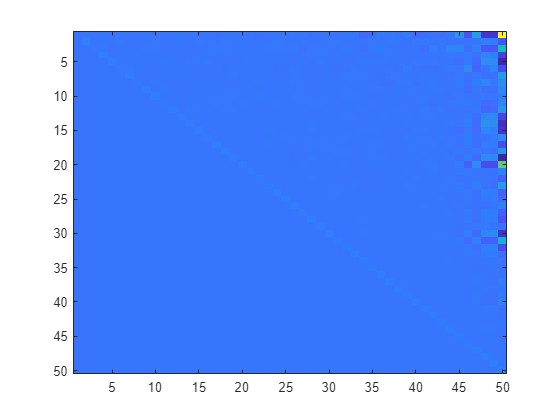

imagesc(logm(H))

A = Generate_Large_Matrix(500);
tic
A = Normal_QR(A,500);
toc

Elapsed time is 70.330954 seconds.


A

A = 1.0e+04 *

    0.0500   -0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000   -0.0000    0.0001   -0.0000    0.0001   -0.0001    0.0000   -0.0000   -0.0000    0.0001   -0.0001    0.0000   -0.0000   -0.0001    0.0001    0.0000   -0.0000   -0.0001    0.0001    0.0001    0.0001    0.0003   -0.0001    0.0002    0.0000   -0.0001   -0.0000    0.0002   -0.0002    0.0001   -0.0001    0.0002    0.0001    0.0001   -0.0002    0.0000    0.0001    0.0004   -0.0002   -0.0000   -0.0002    0.0002    0.0000    0.0000
   -0.0000    0.0498   -0.0001   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0001   -0.0000    0.0000   -0.0000   -0.0001   -0.0001    0.0002   -0.0002    0.0001   -0.0000   -0.0001   -0.0000   -0.0001    0.0001    0.0000   -0.0001   -0.0002    0.0001    0.0001   -0.0001    0.0002   -0.0002    0.0000    0.0000    0.0001   -0.0002    0.0002   -0.0002    0.0000   -0.0001    0.0002   -0.0002    0.0003   -0.0001   -

A = Generate_Large_Matrix(500);
H = Householder_hessenberg(A);
tic
H = Unshifted_QR(H,1000);
toc

Elapsed time is 6.911023 seconds.


H

H = 1.0e+04 *

    0.0500   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000    0.0001    0.0000   -0.0000   -0.0000    0.0000    0.0001   -0.0000   -0.0001   -0.0000    0.0001    0.0000    0.0002   -0.0001   -0.0001    0.0001    0.0002    0.0002    0.0001    0.0000    0.0002    0.0001    0.0002   -0.0002   -0.0001    0.0000    0.0000    0.0000   -0.0001   -0.0003    0.0003   -0.0002    0.0001    0.0001   -0.0000   -0.0001   -0.0004   -0.0001   -0.0001    0.0001   -0.0000
   -0.0000    0.0499   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0002    0.0002    0.0001    0.0002   -0.0000    0.0000    0.0002    0.0001    0.0000   -0.0001   -0.0001   -0.0001   -0.0000    0.0000   -0.0002   -0.0001   -0.0001    0.0001   -0.0002    0.0001   -0.0000   -0.0001    0.0001   -0.0001    0.0001    0.0000    0.0001   -0.0001    

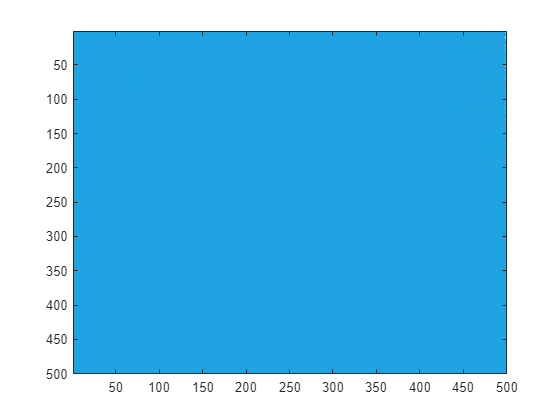

imagesc(H)

A = Generate_Large_Matrix(500);
H = Householder_hessenberg(A);
tic
H = Shifted_QR(H);
toc

Elapsed time is 63.573627 seconds.


H

H = 1.0e+04 *

    0.0001   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0001    0.0000   -0.0000    0.0010   -0.0015   -0.0001    0.0001   -0.0001    0.0002    0.0017    0.0001   -0.0005    0.0000   -0.0003    0.0024   -0.0006   -0.0002   -0.0004   -0.0036   -0.0000   -0.0000   -0.0002   -0.0000   -0.0003   -0.0002    0.0012   -0.0005   -0.0002   -0.0005    0.0000   -0.0027   -0.0024   -0.0004   -0.0000    0.0002   -0.0008   -0.0002    0.0020    0.0027    0.0003    0.0008
         0    0.0002   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0001    0.0000    0.0001    0.0026   -0.0050   -0.0004    0.0004    0.0001    0.0002    0.0010    0.0003   -0.0027   -0.0002   -0.0008    0.0001    0.0009   -0.0004   -0.0004    0.0004    0.0007    0.0001   -0.0002   -0.0066    0.0023    0.0000    0.0016   -0.0003   -0.0009    0.0004   -0.0002    0.0032    0.0008    0.0003   -0.0002    0.0001    0.0008   -0.0006   -0.0025   -0.0057   -

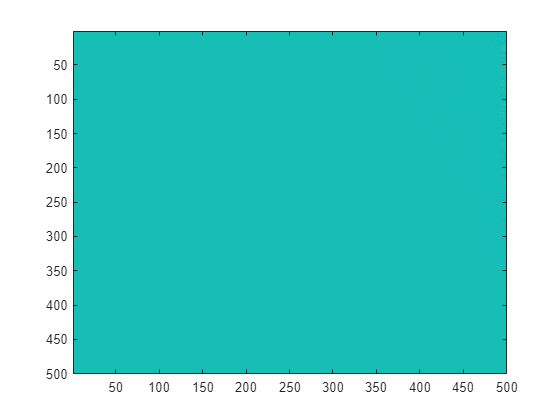

imagesc(H)

A = Generate_Large_Matrix(500);
H = Householder_hessenberg(A);
tic
H = CHASE_THE_BULGE(H);
toc

Elapsed time is 1.718268 seconds.


H

H = 1.0e+04 *

    0.0001    0.0037   -0.0001   -0.0035   -0.0009   -0.0016    0.0004    0.0015   -0.0000   -0.0007    0.0001    0.0020   -0.0004   -0.0033   -0.0004   -0.0013    0.0001   -0.0024   -0.0004    0.0003    0.0002   -0.0020    0.0004    0.0027   -0.0008   -0.0003   -0.0008   -0.0004    0.0000   -0.0001    0.0012   -0.0002    0.0009    0.0004    0.0015   -0.0001    0.0018   -0.0006    0.0003    0.0039    0.0010   -0.0011   -0.0032   -0.0020    0.0007    0.0010    0.0004    0.0006   -0.0008    0.0015
         0    0.0500   -0.0006    0.0000   -0.0002   -0.0001   -0.0002    0.0000    0.0022    0.0002   -0.0018   -0.0000   -0.0039    0.0004   -0.0030   -0.0003    0.0014   -0.0001   -0.0007    0.0001    0.0033    0.0003   -0.0007    0.0005   -0.0026    0.0008   -0.0026   -0.0010    0.0000    0.0001    0.0004    0.0001   -0.0001    0.0020    0.0001   -0.0004   -0.0003   -0.0035   -0.0023    0.0002    0.0010    0.0003    0.0007   -0.0008    0.0021    0.0000   -0.0012    0.0024   -

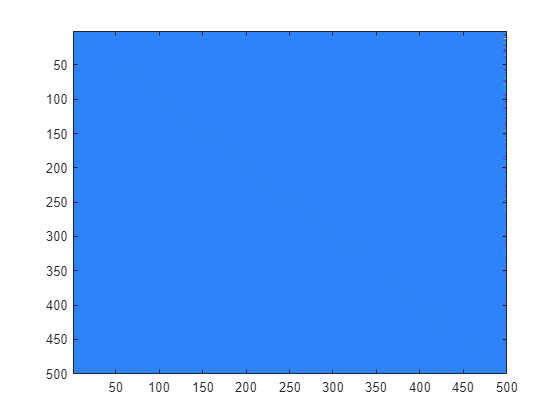

imagesc(H)

## Implementazioni:

### Simple QR

function A = Normal_QR(A, max_iter)
    for i=1:max_iter
        [Q,R] = mgs(A);
        A = R*Q;
    end
end

### Hessenberg Reduction

function A = Hessenberg_reduction(A)
    [num_rows, num_cols] = size(A);
    %itero sugli indici appena trovati
    for col=1:num_cols-1
        for row=num_cols:-1:2+col
            % trova gli indici della matrice di givens unando come pivot [col, col](sempre != 0)
            [c, s] = Givens_Rotation_Matrix_Entries(A(row-1, col), A(row, col));
            %si costruisce la matrice di givens partendo dall'identità
            G = eye(num_rows);
            %assegna gli indici trovati precedentemente alla matrice di givens
            G(row-1, row-1) = c;
            G(row, row) = c;
            G(row, row-1) = -s;
            G(row-1, row) = s;
            %annichilisce l'elemento in posizione A[row, col]
            A = G*A*G';
            if abs(A(row, col)) < 1.e-16
                A(row,col) = 0;
            end
        end
    end
end

function [c, s] = Givens_Rotation_Matrix_Entries(a, b)
    r = hypot(a,b);
    c = a/r;
    s = b/r;
end

### Hessenberg QR Unshifted:

function H = Unshifted_QR(H,max_iter)
    num_cols= length(H);
    %itero sugli indici appena trovati
    G = zeros(2);
    for i=1:max_iter
        for col=1:num_cols-1
            % trova gli indici della matrice di givens unando come pivot [col, col](sempre != 0)
            [c, s] = Givens_Rotation_Matrix_Entries(H(col, col), H(col+1, col));
            %si costruisce la matrice di givens partendo dall'identità
            %assegna gli indici trovati precedentemente alla matrice di givens
            G(1,1) = c;
            G(2,2) = c;
            G(2,1) = -s;
            G(1,2) = s;
            tmp{col} = G';
            %annichilisce l'elemento in posizione A[col+1, col]
            H(col:col+1,col:num_cols) = G*H(col:col+1,col:num_cols);
        end
        for col=1:num_cols-1
           H(1:col+1,col:col+1) = H(1:col+1,col:col+1)*tmp{col};
        end
    end
end

### Shifted QR

function H = Shifted_QR(H)
    num_rows = length(H);
    for m=num_rows:-1:2
        while abs(H(m,m-1)) ~= 0
            [Q, R] = qr(H-H(m,m)*eye(num_rows));
            H = R*Q+H(m,m)*eye(num_rows);
        end
    end
end

### **Modified Gram-Schmidt**

function [Q,R] =  mgs(X)
    [n,p] = size(X);
    Q = zeros(n,p);
    R = zeros(p,p);
    for k = 1:p
        Q(:,k) = X(:,k);
        for i = 1:k-1
            R(i,k) = Q(:,i)'*Q(:,k);
            Q(:,k) = Q(:,k) - R(i,k)*Q(:,i);
        end
        R(k,k) = norm(Q(:,k))';
        Q(:,k) = Q(:,k)/R(k,k);
    end
end

## HOUSEHOLDER FREESTYLE

function H = Householder_hessenberg(A)
    n = length(A);
    for k=1:n-2
        tmp = A(k+1:n,k);
        tmp2 = norm(tmp');
        zer = zeros(1,n-k);
        zer(1) = 1;
        V1 = tmp' + tmp2*zer;
        c = 2/(V1*V1');
        P = eye(n-k) - c*V1'*V1;
        A(k+1:n,k:n) = P*A(k+1:n,k:n);
        A(1:n,k+1:n) = A(1:n,k+1:n)*P';
    end
    H = A;
end

function H = CHASE_THE_BULGE(H)
    n = length(H);
    p = n;
    while p > 2
        q = p-1;
        s = H(q,q) + H(p,p);
        t = H(q,q)*H(p,p) - H(q,p)*H(p,q);
        x = H(1,1)*H(1,1) + H(1,2)*H(2,1) - s*H(1,1) + t;
        y = H(2,1)*(H(1,1) + H(2,2) - s);
        z = H(2,1)*H(3,2);

        for k=0:p-3
            P = reflector([x,y,z]);
            r = max(1,k);
            H(k+1:k+3,r:n) = P'*H(k+1:k+3,r:n);
            r = min(k+4,p);
            H(1:r,k+1:k+3) = H(1:r,k+1:k+3)*P;
            x = H(k+2,k+1);
            y = H(k+3,k+1);
            if k < p-3
                z = H(k+4,k+1);
            end
        end

        G = eye(2);
        [c, s] = Givens_Rotation_Matrix_Entries(x, y);
        G(1,1) = c;
        G(2,2) = c;
        G(2,1) = -s;
        G(1,2) = s;
        H(q:p,p-2:n) = G*H(q:p,p-2:n);
        H(1:p,p-1:p) = H(1:p,p-1:p)*G';
        %Check for convergence
        if abs(H(p,q)) < (1e-5 * (abs(H(q,q)) + abs(H(p,p))))
            H(p,q) = 0;
            p = p-1;
            q = p-1;
        elseif abs(H(p-1,q-1)) < (1e-5 * (abs(H(q-1,q-1)) + abs(H(q,q))))
            H(p-1,q-1) = 0;
            p = p-2;
            q = p-1;
        end
    end
end

function P = reflector(V)
    tmp2 = norm(V');
    zer = zeros(1,length(V));
    zer(1) = 1;
    V1 = V + tmp2*zer;
    c = 2/(V1*V1');
    P = eye(length(V)) - c*V1'*V1;
end

function A = Generate_Large_Matrix(n)
    D = diag(1:n);
    S=rand(n); 
    S = (S - .5)*2;
    A = S*D/S;
end



